**Problem 1**

The magic happens in the attached file myhinfsyn.m.  This just calls and compares with the standard Matlab solution.

First build the given model.

A = [-0.2 2 2 0;0 -1 0 0;0 0 -2 0;0 0 0 -10];
B = [2 1 0;40 20 -20; 60 30 -30;-2 -1 -3];
C = [1 0 0 -1;3 0 0 -3;0 1 1 0];
D = [0 0 0.9487;0 0 -0.3162;-0.4472 0.8944 0];
P = ss(A,B,C,D);

Now call the two synthesis routines and compare results.

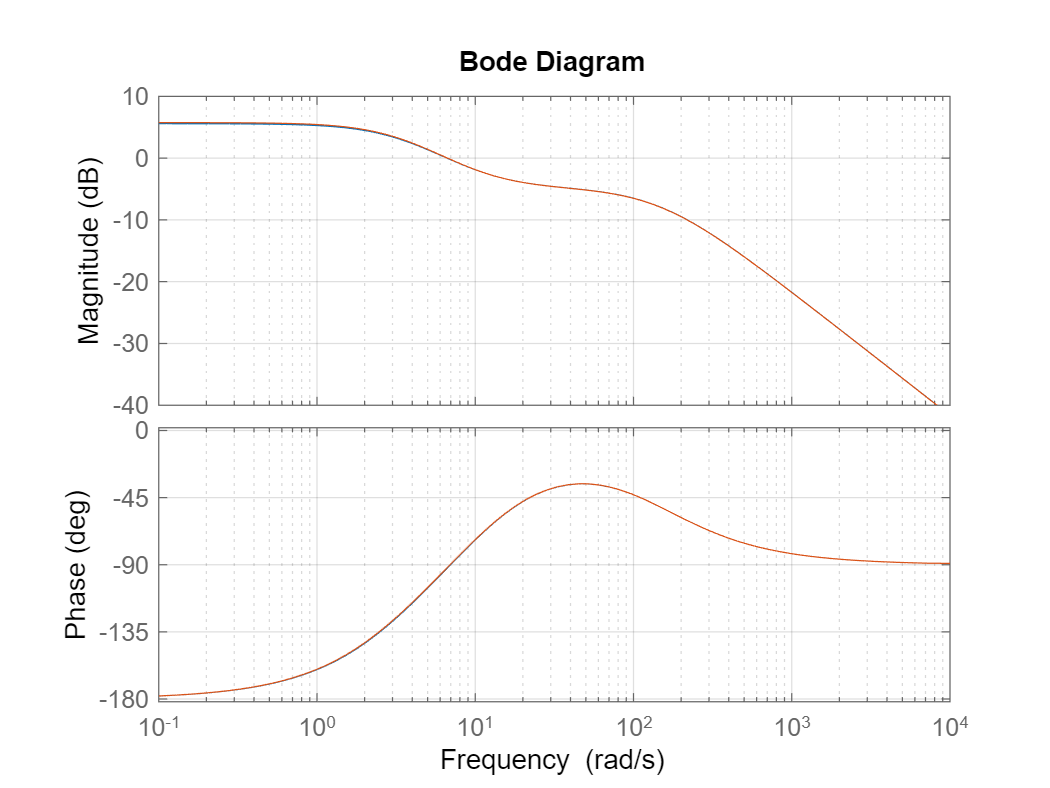

myK = myhinfsyn(P,1,1);
K = hinfsyn(P,1,1);
bode(myK,K)

They are on top of each other, so I would consider that a success!

**Problem 2**

Again, the magic happens off-page in myh2syn.m.  We're using the same model, so just compute and compare.

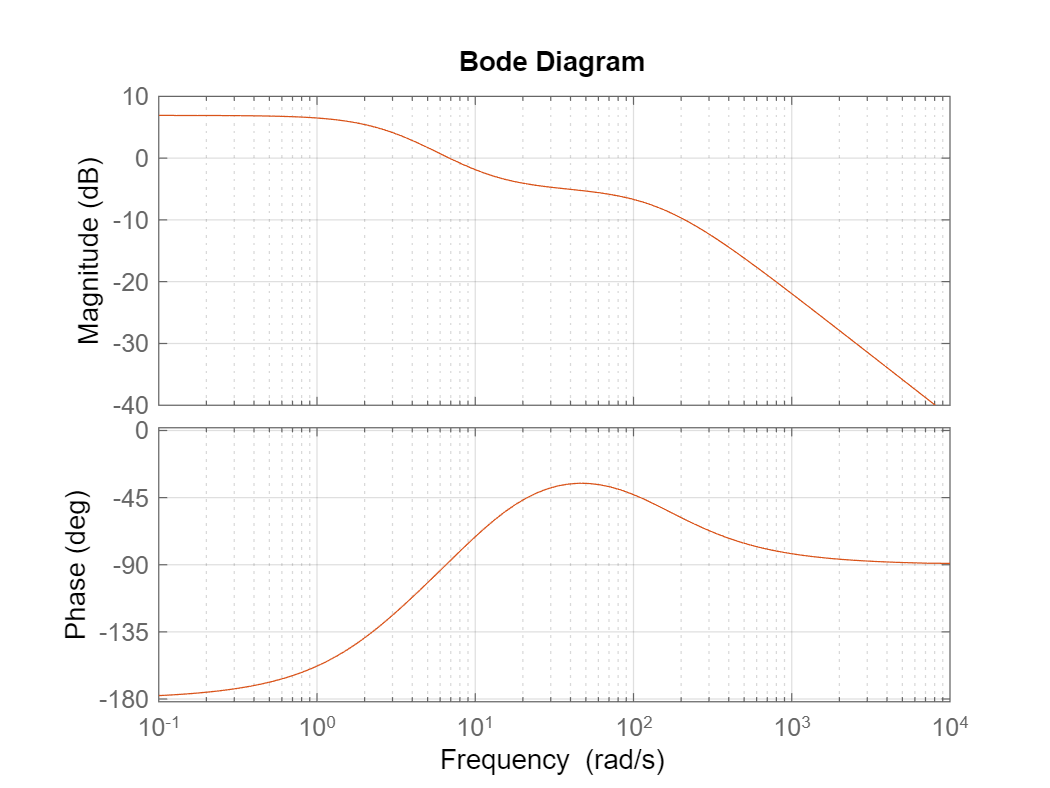

myK2 = myh2syn(P,1,1);
K2 = h2syn(P,1,1);
bode(myK2,K2)

Again, the controllers overlap.

**Problem 3**

First build the model.

A = [0 1 0 0 0 0;-20 -0.2 20 0.02 0 0;0 0 0 1 0 0;20 0.2 -120 -0.12 40 0.4;0 0 0 0 0 1;0 0 100 0.1 -44 -0.44];
B = [0 0.2 0 -0.2 0 0]';
C = [1 0 1 0 0 0];
D = 0;
model = ss(A,B,C,D);

Let's try:

Q = diag([1e6 0 1e6 0 0 0]);
R = 0.11;
W = eye(6);
V = 1e-8;
Klqg = lqg(model,blkdiag(Q,R),blkdiag(W,V));

Inputting this into the model MSD_solutions.slx yields the following step disturbance response.

m1 = 5;
k1 = 100;
c1 = 1;

m2 = 1;
k2 = 100;
c2 = 0.1;

m3 = 10;
k3 = 40;
c3 = 0.4;
Ksim = Klqg;
sim('MSD_solutions');

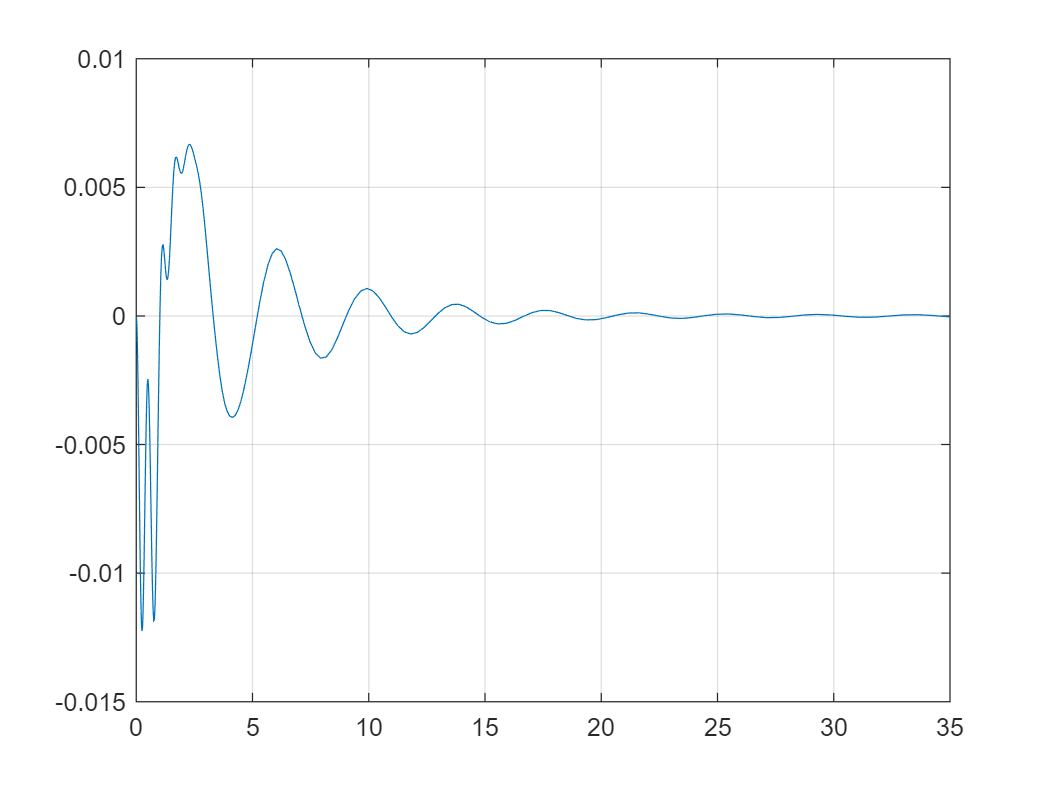

plot(x2.Time,x2.Data)
grid

The response is oscillatory, but stable.

Now it's time to perform the $H_\infty$ loop shaping design.  I'll use *ncfsyn* because it too provides a positive feedback design.  The negative sign in the design is due to the fact that the LQG controller uses positive feedback as well.

[Kls,CL,GAM] = ncfsyn(model,Klqg);
GAM

GAM = 1.7417

Based on this value of $\gamma$, we can withstand normalized coprime factor uncertainty of size

ep = 1/GAM

ep = 0.5741

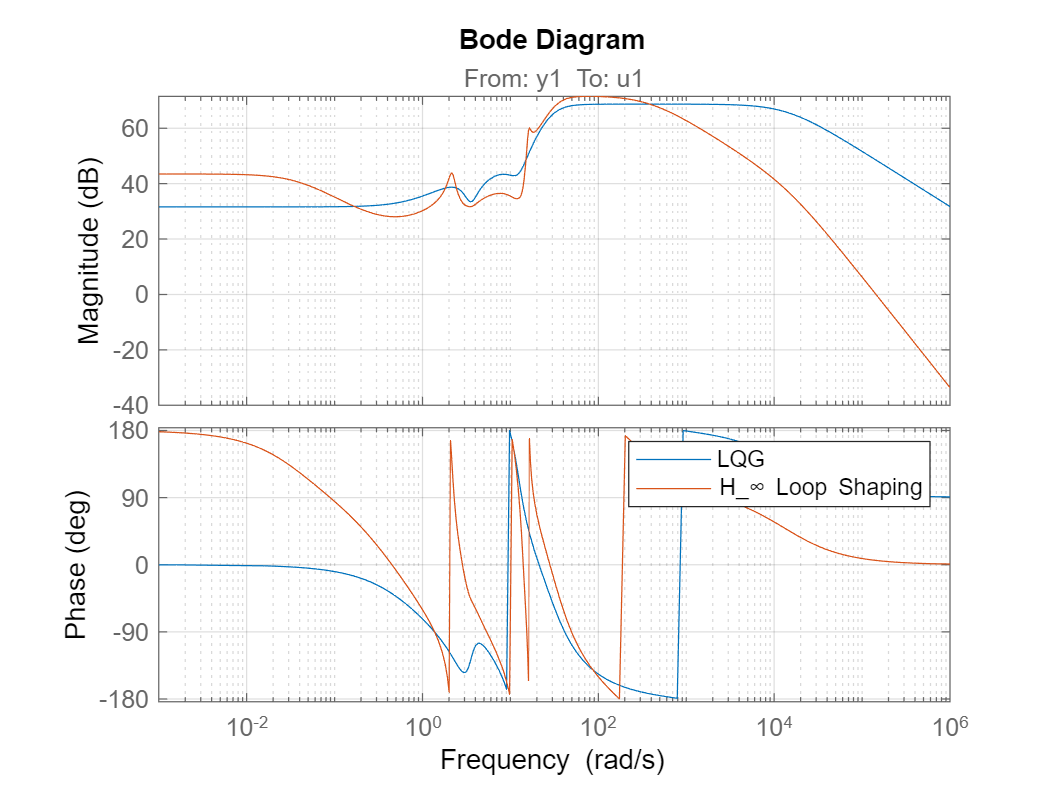

bode(Klqg,Kls)
legend('LQG','H_\infty Loop Shaping')

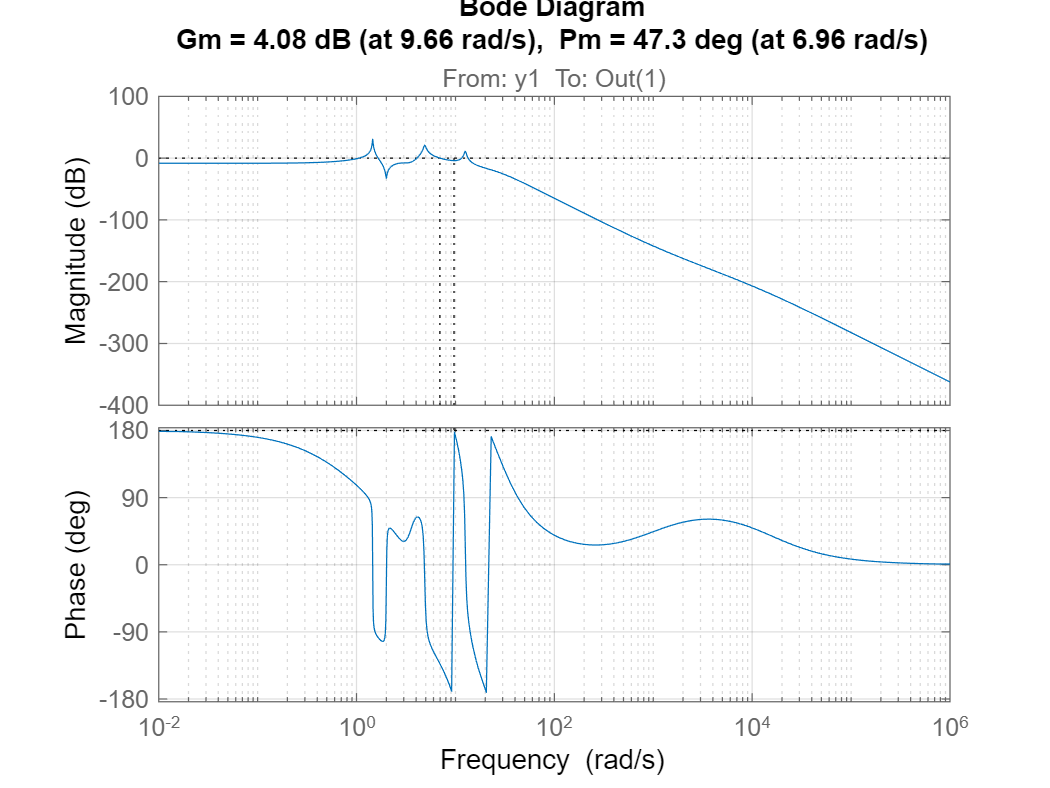

margin(-model*Klqg)

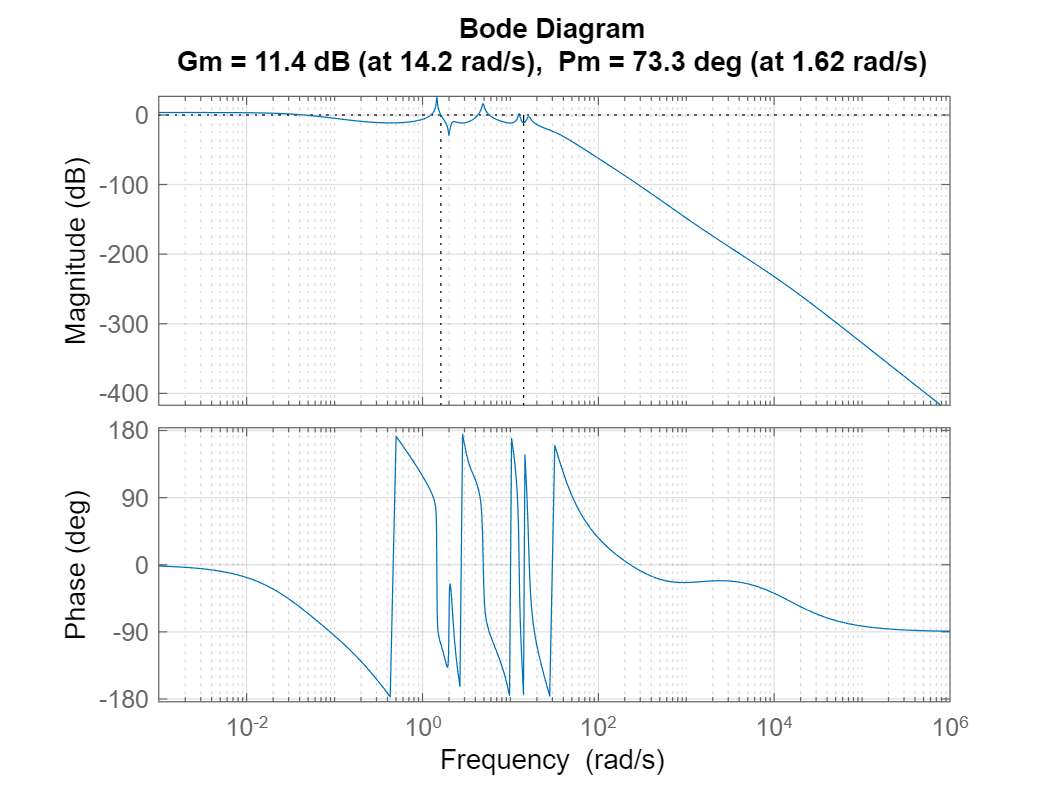

margin(-model*Kls)

The results with this controller are quite similar as seen below, but it has much higher stability margins as seen above.

Ksim = Kls;
sim('MSD_solutions');

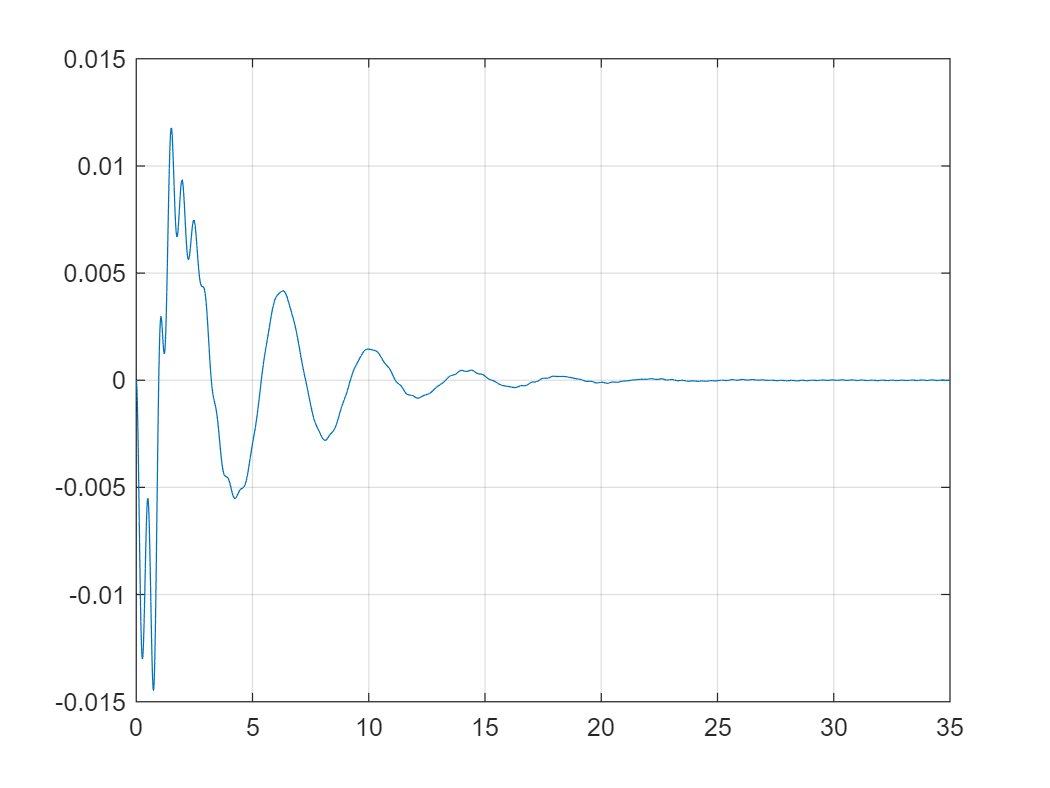

plot(x2.Time,x2.Data)
grid

The LQG results are below for the uncertain simulation.

K = Klqg;
%Uncertain parameter range
p = 20;

%Uncertain Parameters
uVec1=ureal('a',1,'Percentage',p);
usamp1=usample(uVec1,100);
%Simulates with params
for i=1:5
    paramNameValStruct.SaveOutput = 'on';
    m2 = usamp1(:,:,i);
    sim('MSD_solutions');
    outx2(:,i)=x2;
end

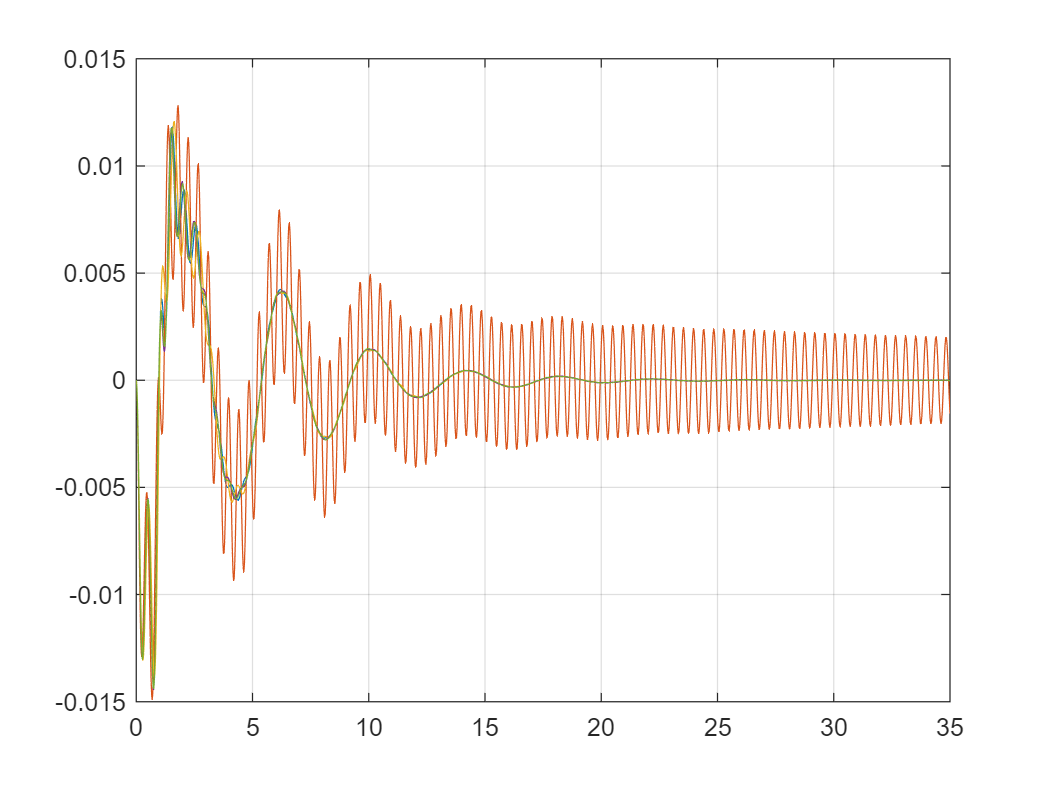

for i=1:5
    plot(outx2(:,i).time,outx2(:,i).data(:,1));
    hold on
end
hold off
grid

The plot for $H_\infty$ loop shaping is shown below.  

K = Kls;
%Simulates with params
for i=1:5
paramNameValStruct.SaveOutput = 'on';
m2 = usamp1(:,:,i);
sim('MSD_solutions');
outx2(:,i)=x2;
end

for i=1:5
    plot(outx2(:,i).time,outx2(:,i).data(:,1));
    hold on
end
hold off
grid

The mass variability creates oscillations in the output for both controllers.  Your performance will vary depending on your LQG design / uncertainty samples.

Note that for this particular type of uncertainty (uncertain mass), there appears to be VERY little difference in the robustness of the design.

**Problem 4**

Part a

Grab the data into the workspace.

load respdata

The data are now available in the variable "sys".  

To fit the system, I want to get the average of the responses.

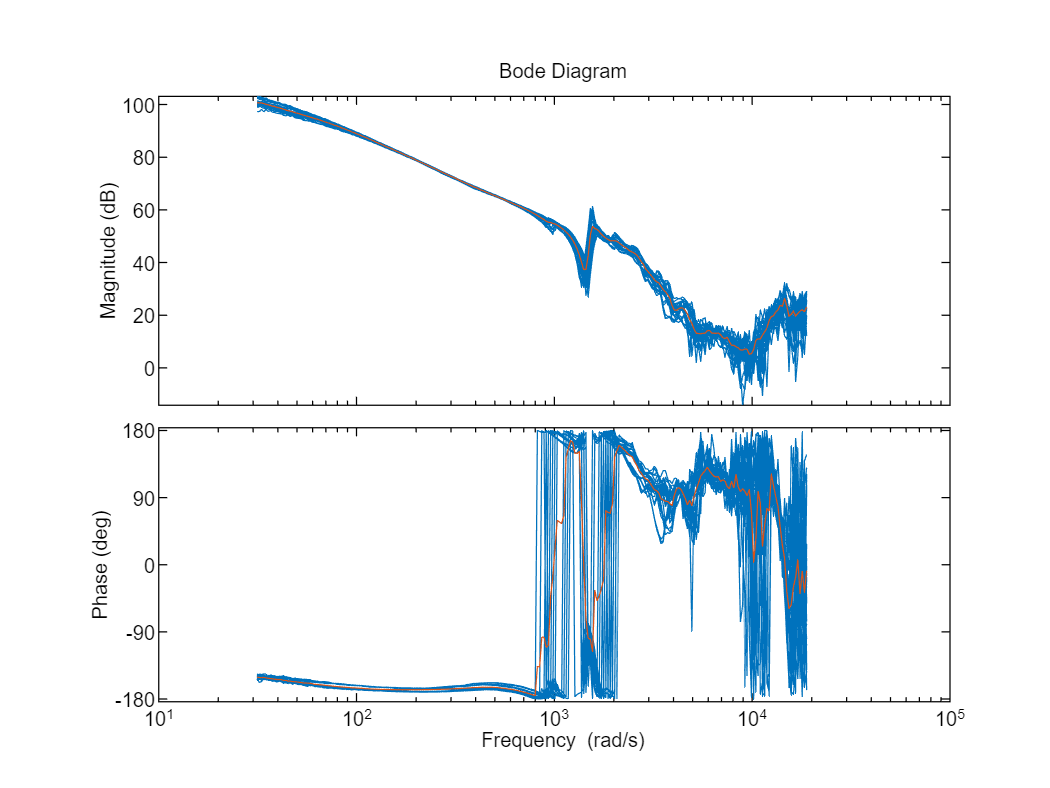

[resp,freq] = frdata(sys);
mag = abs(resp);
magavg = mean(mag,4);
magavg = magavg(:);
phase = angle(resp);
phaseavg = mean(phase,4);
phaseavg = phaseavg(:);
respavg = magavg.*exp(phaseavg*j);
avgsys = frd(respavg,freq);
opt = bodeoptions;
opt.PhaseWrapping = 'on';
bode(sys,avgsys,opt)

Now I need to fit a model, and subsequently weights on the uncertainty.

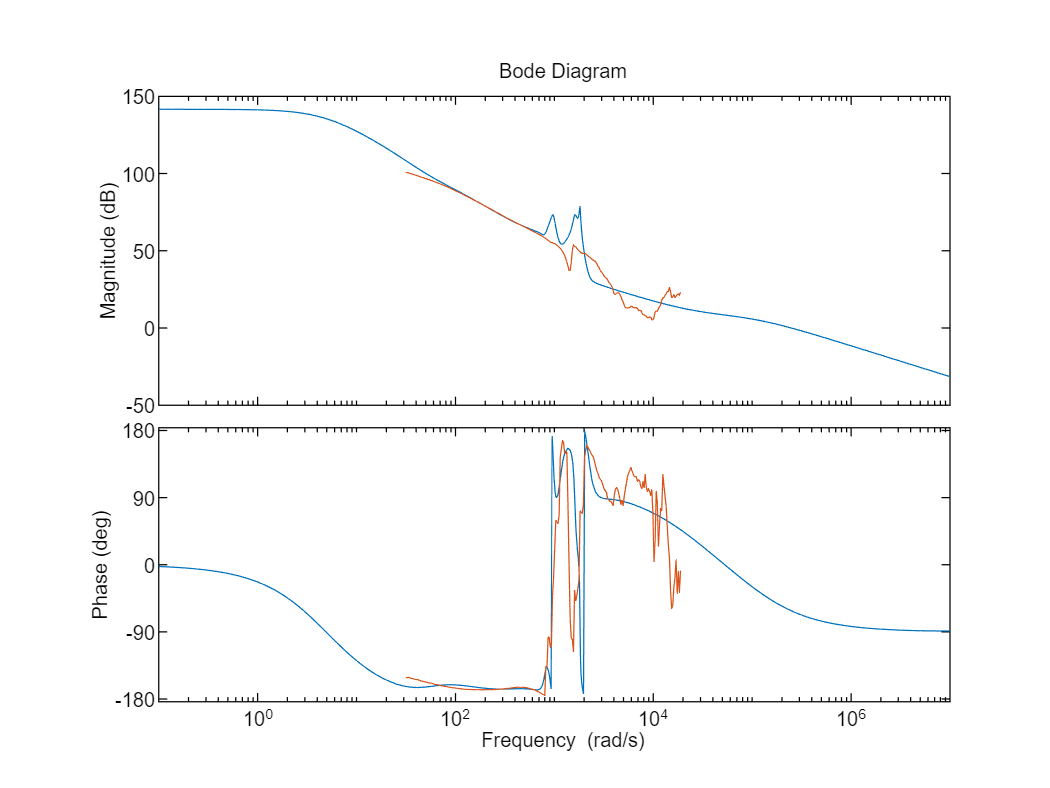

s = tf('s');
G = fitfrd(avgsys,14,[],[],2)*1e5/(s+1e5);  %Try a 14th order model; extra argument ensures stable
bode(G,avgsys,opt)

Now I can move onto the fits.

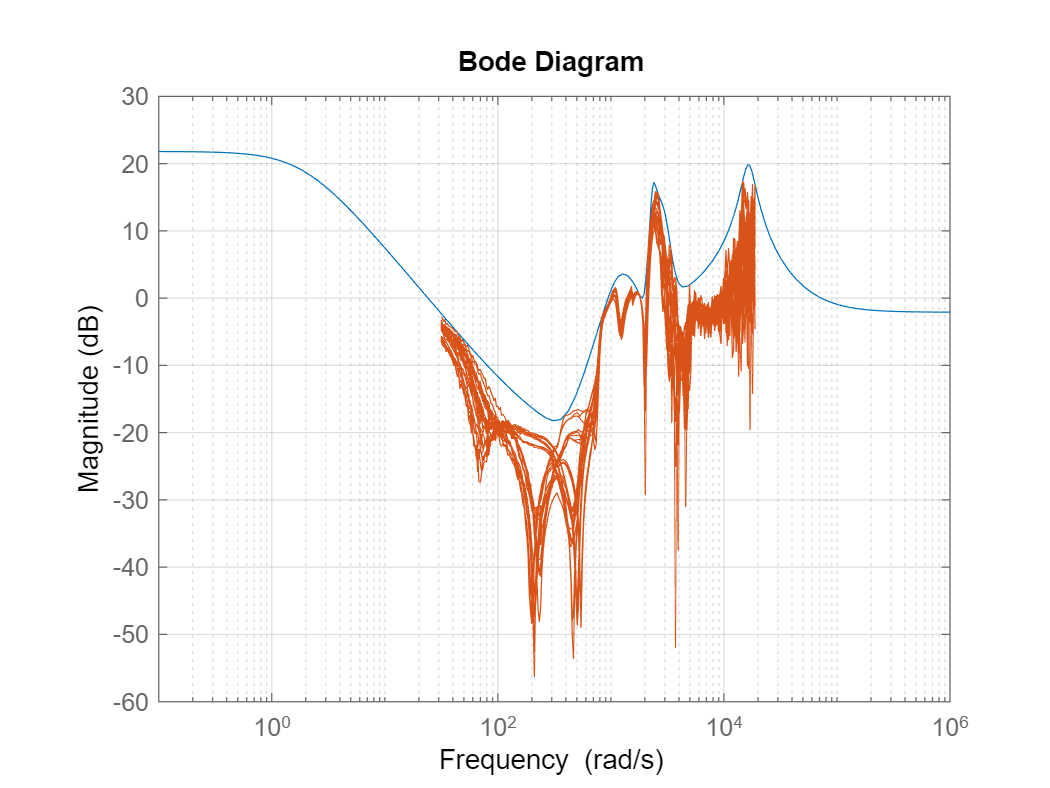

[Pmult,info] = ucover(sys,G,9);
bodemag(info.W1,(sys-G)/G);

It's pretty good, but the high DC gain will break the design.  I'll drop it with a pole/zero pair.

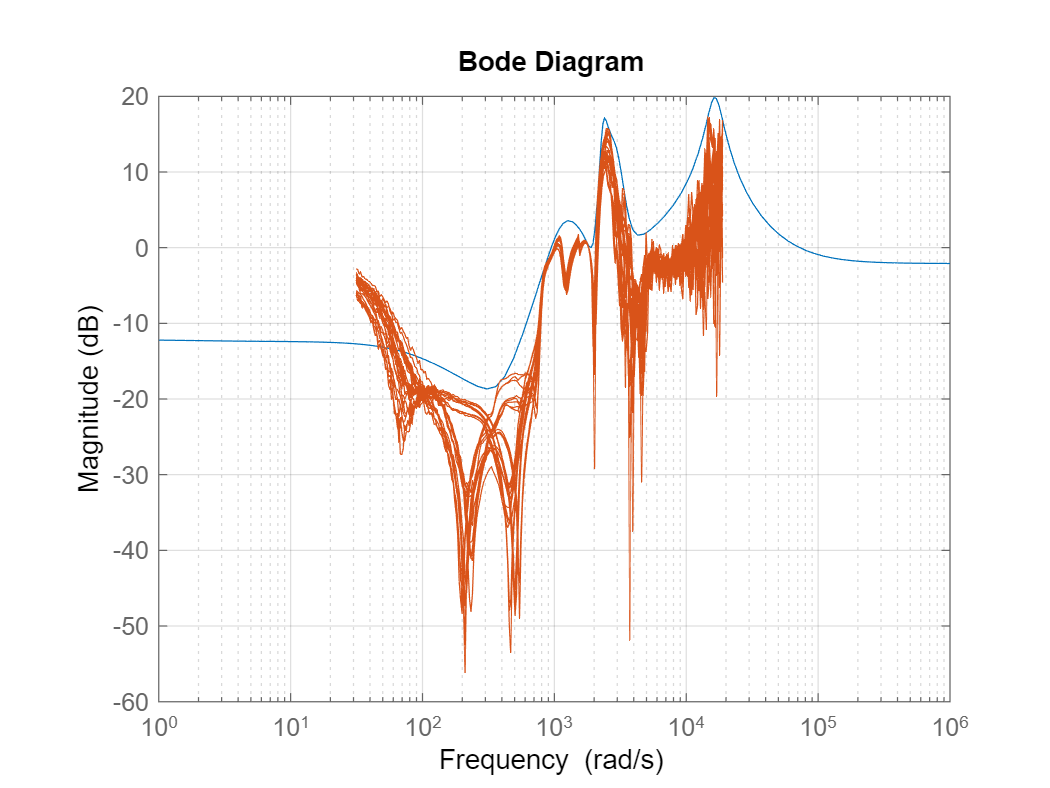

Wt = info.W1*(s+2)/(s+100);
bodemag(Wt,(sys-G)/G);

Using this weight I'll now build the uncertain plant.

Delta = ultidyn('Delta',[1 1]);
Gunc = G*(1+Wt*Delta);

Part b

Now on to controller design.

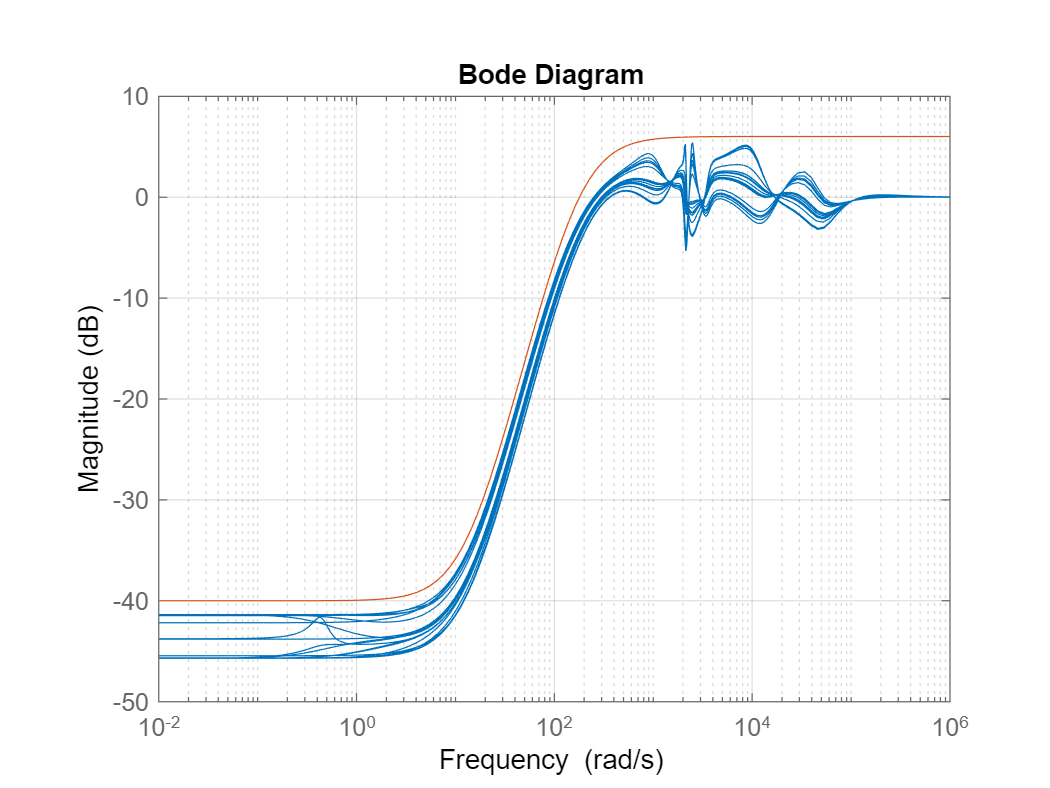

wh = 2000;  %I probed a bit to come up with this
wl = 0;
w_try = wh;
w_new = 1/2*(wh+wl);
while(abs(w_new-w_try)>.01)  %Stopping criterion
    w_try = w_new;
    Wp = makeweight(sqrt(100),w_try,sqrt(1/2))^2;
    [K,CL,GAM] = mixsyn(G,Wp,[],Wt);  %Mixsyn solves this problem
    S = 1-feedback(Gunc*K,1);  
    perfmarg = robustperf(Wp*S);
    mu = 1/perfmarg.UpperBound;
    if mu<1
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
end
bodemag(S,1/Wp)

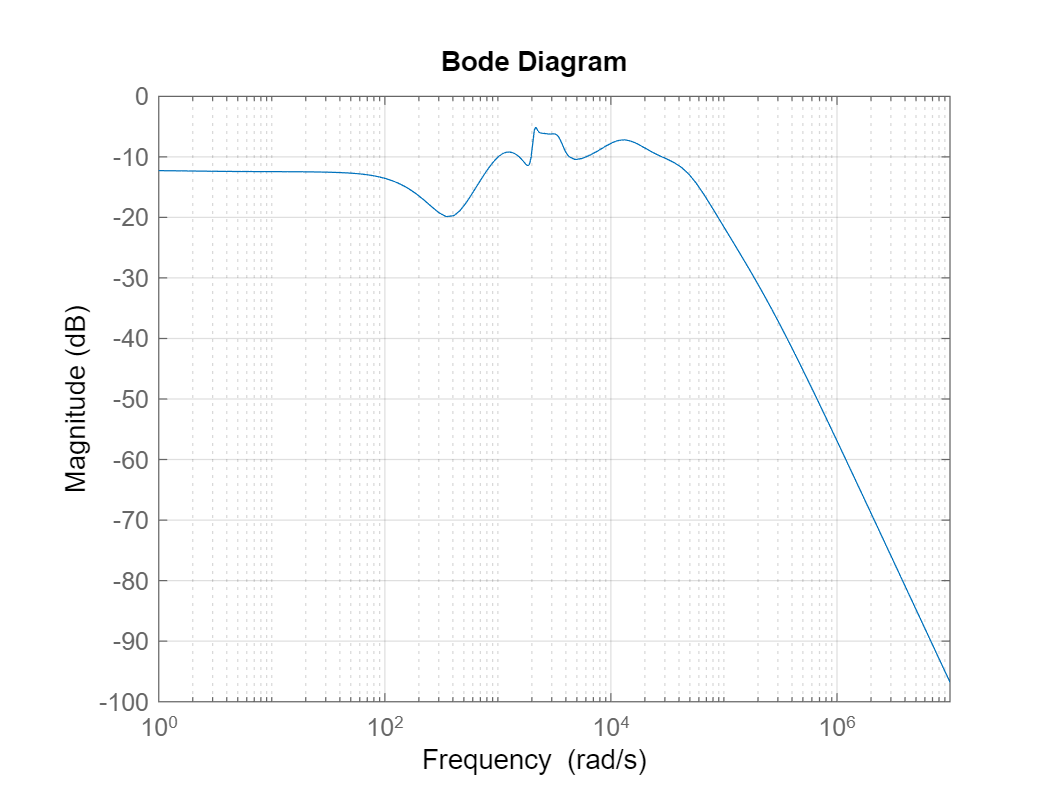

bodemag(Wt*(1-S.NominalValue))

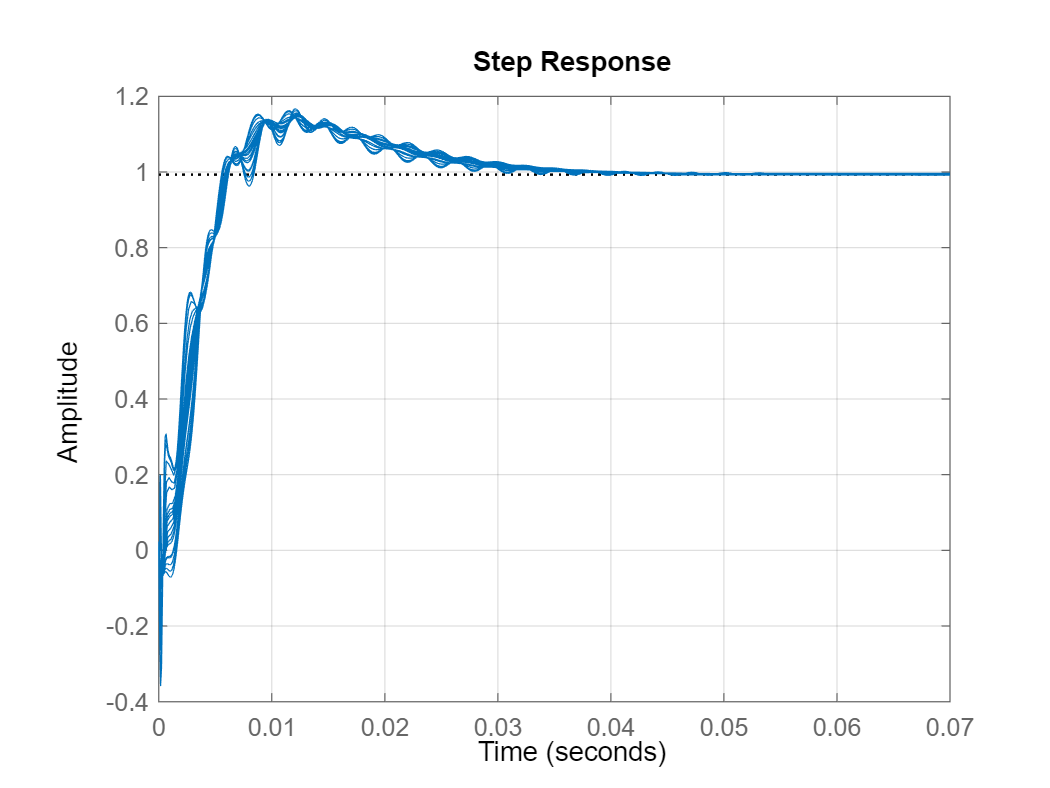

T = 1-S;
step(T);

## $H_\infty$ Synthesis Command

%This homemade function solves the simplified H_infty control problem as
%described in Zhou Section 14.2.  It DOES NOT check that the assumptions
%hold, so user beware!

function K = myhinfsyn(G,nmeas,ncont);
[A,B,C,D] = ssdata(ss(G));  %Extract SS matrices
%Partition matrices
B1 = B(:,1:size(B,2)-ncont);
B2 = B(:,size(B,2)-ncont+1:end);
C1 = C(1:size(C,1)-nmeas,:);
C2 = C(size(C,1)-nmeas+1:end,:);
D12 = D(1:size(C,1)-nmeas,size(B,2)-ncont+1:end);
D21 = D(size(C,1)-nmeas+1:end,1:size(B,2)-ncont);
%%%%%%%%%%%%%%%%%%%Find gamma%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Now bisect until the solution exists
ul =1e5;
ll = max([1e-5,norm(D)]);
g_new = mean([ul,ll]);
g_try = ul;
while(abs(g_new-g_try)>.0001)  %Stopping criterion
   g_try = g_new;
   try
   Xinf = are(A,B2*B2'-B1*B1'/g_try^2,C1'*C1);
   Yinf = are(A',C2'*C2-C1'*C1/g_try^2,B1*B1');
   rho = max(abs(eig(Xinf*Yinf)))-g_try^2;
   if (rho<0)
       ul = g_try;
   else
       ll = g_try;
   end
   catch
       ll = g_try;
   end
    g_new = 1/2*(ll+ul);
end
%%%%%%%%%%%%%%Build Controller%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Finf = -B2'*Xinf;
Linf = -Yinf*C2';
Zinf = inv(eye(size(Xinf))-g_try^(-2)*Yinf*Xinf);
Ainf = A+g_try^(-2)*B1*B1'*Xinf+B2*Finf+Zinf*Linf*C2;
K = ss(Ainf,-Zinf*Linf,Finf,0);
end

## $H_2$ Synthesis Command

%This homemade function solves the simplified H_2 control problem with the
%assumptions described in Zhou Section 14.2.  It DOES NOT check that the 
%assumptions hold, so user beware!
function K = myh2syn(G,nmeas,ncont);
[A,B,C,D] = ssdata(ss(G));  %Extract SS matrices
%Partition matrices
B1 = B(:,1:size(B,2)-ncont);
B2 = B(:,size(B,2)-ncont+1:end);
C1 = C(1:size(C,1)-nmeas,:);
C2 = C(size(C,1)-nmeas+1:end,:);
D12 = D(1:size(C,1)-nmeas,size(B,2)-ncont+1:end);
D21 = D(size(C,1)-nmeas+1:end,1:size(B,2)-ncont);
%%%%%%%%%%%%%%%%%%%Solve AREs%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
X2 = are(A,B2*B2',C1'*C1);  %I kept simple (matched Hinf assumptions)
Y2 = are(A',C2'*C2,B1*B1');
%%%%%%%%%%%%%%Build Controller%%%%%%%%%%%%%%%%%%%%%%%%%%%%
F2 = -B2'*X2;
L2 = -Y2*C2';
K = ss(A+B2*F2+L2*C2,-L2,F2,0);
end